Import the :boston night.jpg" picture convert it to HSV color space

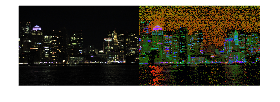

img_rgb = imread("boston night.jpg");
img_hsv = rgb2hsv(img_rgb);
montage({img_rgb,img_hsv})

V = img_hsv(:,:,3); % original V

- Perform gamma correction Y = 1/2

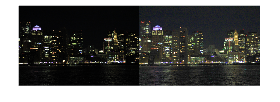

gamma = 1/2;
V_gamma = V .^ gamma; % V_gamma adjusted
img_hsv_corrected = img_hsv;  
img_hsv_corrected(:, :, 3) = V_gamma;
img_corrected_rgb = hsv2rgb(img_hsv_corrected);
montage({img_rgb, img_corrected_rgb})

2. Use imadjust 

V_adjust = imadjust(V);

3. use histeq

V_histeq = histeq(V);

4. use adapthisteq

V_adapthisteq = adapthisteq(V);

New HSV images with adjusted Value channels

hsv_gamma = img_hsv;
hsv_gamma(:,:,3) = V_gamma;

hsv_imadjust = img_hsv;
hsv_imadjust(:,:,3) = V_adjust;

hsv_histeq = img_hsv;
hsv_histeq(:,:,3)= V_histeq;

hsv_adapthisteq = img_hsv;
hsv_adapthisteq(:,:,3)= V_adapthisteq;


Conversion back to RGB colorspace

rgb_gamma = hsv2rgb(hsv_gamma);
rgb_imadjust = hsv2rgb(hsv_imadjust);
rgb_histeq = hsv2rgb(hsv_histeq);
rgb_adapthisteq = hsv2rgb(hsv_adapthisteq);

Conversion from double to uint8 datatype

rgb_gamma_uint8 = im2uint8(rgb_gamma);
rgb_imadjust_uint8 = im2uint8(rgb_imadjust);
rgb_histeq_uint8 = im2uint8(rgb_histeq);
rgb_adapthisteq_uint8 = im2uint8(rgb_adapthisteq);

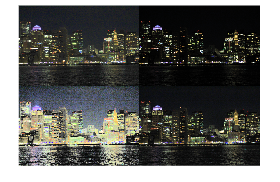

% Displaying the results

montage({rgb_gamma_uint8, rgb_imadjust_uint8, rgb_histeq, ...
    rgb_adapthisteq_uint8})